fname = POI.Path + "/1/20220818_194419_6560.wav";
x = audioread(fname);
div = 16;
N = numel(x)/div;
x = x((1:N));

gpuDevice(1); %reset GPU
fb = SFB(16, 0.05, 2000, numel(x), 25);

tic
for i = 1:16
    s = fb.filterS(x);
end
toc

Elapsed time is 2.537271 seconds.


tic
for i = 1:16
    S = POI.PowerSpectrum(x);
end
toc

Elapsed time is 0.501966 seconds.


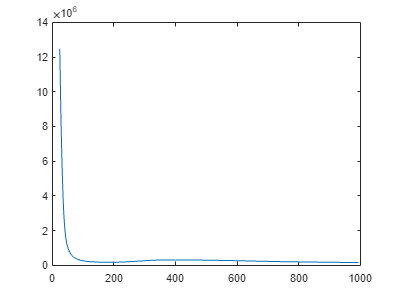

% file = "D:\Whale Data\Brydes Whale 20220719\6252.211114000012_8.wav";
file = "D:\Whale Data\False Bay whale songs\song 1.wav";
[x, fs] = audioread(file);
x = resample(x, 1, fs/2000);
gpuDevice(1); %reset GPU
fb = SFB(16, 0.05, 2000, numel(x), 25);
s = fb.filterS(x);
s = s.^2;

w = POI.NoiseEstimate(s);
sw = s./w;

[H, probs, mu_ns, mu_s, sigma_ns, sigma_s, comp_ns, comp_s, converged, n_iter, LL, mon, fmin, fmax, Ht, contam] = SignalDetection.softSignalDetectionGMM(sw, 7);


figure
plot(fb.fc, w'./(fb.fc/fb.Q));

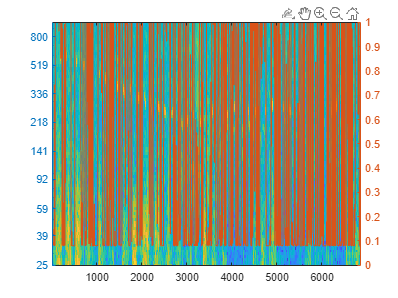



figure
yyaxis left
imagesc(1:size(s, 2), fb.fc, log(sw));
set(gca, "YDir", "normal")
set(gca, "YScale", "log")
set(gca, 'ytick', round(fb.fc(1:10:end),0));
ylim([min(fb.fc), max(fb.fc)])
yyaxis right
plot(probs);

gpuDevice(1); %reset GPU
x = gpuArray(single(rand(numel(x), 1)));
h = gpuArray(single(rand(4096, 1) + 1j));
tic
for i = 1:16
    r = conv(x, h);
end
toc

Elapsed time is 0.019418 seconds.


fb = SFB(16, 0.05, 2000, 2^18, 25);
savepath = sprintf("%s/spectrograms/filterbank.mat", POI.Path);
% save(savepath, "fb", "-mat");

wb = waitbar(0);
parforWaitbar(wb, 3180);
wtq = parallel.pool.DataQueue;
afterEach(wtq,@parforWaitbar);

for ds = 1:2
    path = sprintf("%s/%d", POI.Path, ds);
    files = dir(path);
    files = files(~[files.isdir]);
    for i = 1:5
        fname = files(i).name;
        fpath = sprintf("%s/%s", path, fname);
        xTotal = audioread(fpath);
        xTotal = 1:numel(xTotal);
        N = numel(xTotal)/16;
        for n = 1:16
            try
                x = xTotal((n-1)*N+1:(n)*N);
                s = fb.filterS(x);
                savepath = sprintf("%s/spectrograms/%d/%s_segment%d.mat", POI.Path, ds, fname(1:20), n);
                save(savepath, "s", "-mat");
                send(wtq,[]);
            catch err
                disp(getReport(err,'extended'));
            end
        end
    end
end
close(wb)

